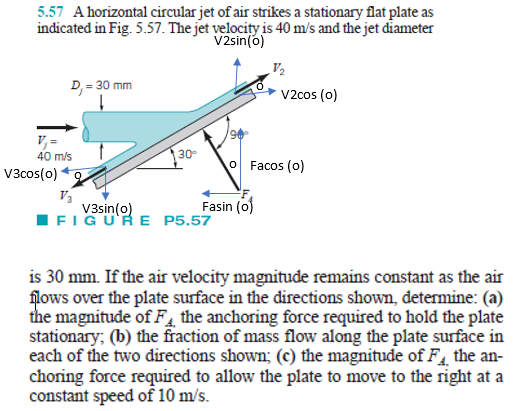

# inflow properties

% ----------------
u = symunit;
rho = 1.23*u.kg/u.m^3;
D1 = 30*u.mm;
A1 = sympi*D1^2/4;
% ----------------
V1 = 40*u.m/u.s;
Vcv = 10*u.m/u.s;
% ----------------
W1_a = V1;
W1x_a = W1_a;
W1y_a = 0;
% ----------------
W1_c = abs(V1-Vcv);
W1x_c = W1_c;
W1y_c = 0;
% ----------------
mdot1_a = rewrite(rho*A1*W1_a, 'SI');
mdot1_c = rewrite(rho*A1*W1_c, 'SI');
% ----------------

# outflow properties

% ----------------
theta = 30*u.deg;
% ----------------
W2_a = W1_a;
W2x_a = W2_a*cos(theta);
W2y_a = W2_a*sin(theta);
W3_a = W1_a;
W3x_a = W3_a*cos(theta);
W3y_a = W3_a*sin(theta);
% ----------------
W2_c = W1_c;
W2x_c = W2_c*cos(theta);
W2y_c = W2_c*sin(theta);
W3_c = W1_c;
W3x_c = W3_c*cos(theta);
W3y_c = W3_c*sin(theta);
% ----------------

# conservation of mass

% ----------------
syms mdot2_a mdot3_a;
eqn_a = sym.zeros(3,1);
eqn_a(1) = mdot1_a == mdot2_a+mdot3_a;
% ----------------
syms mdot2_c mdot3_c;
eqn_c = sym.zeros(3,1);
eqn_c(1) = mdot1_c == mdot2_c+mdot3_c;
% ----------------

# conservation of momentum (x-direction)

% ----------------
syms F_a;
Fx_a(F_a) = F_a*sin(theta);
eqn_a(2) = -Fx_a == -mdot1_a*(W1x_a)+mdot2_a*(W2x_a)+mdot3_a*(-W3x_a);
% ----------------
syms F_c;
Fx_c(F_c) = F_c*sin(theta);
eqn_c(2) = -Fx_c == -mdot1_c*(W1x_c)+mdot2_c*(W2x_c)+mdot3_c*(-W3x_c);
% ----------------

# conservation of momentum (y-direction)

% ----------------
Fy_a(F_a) = F_a*cos(theta);
eqn_a(3) = Fy_a == -mdot1_a*(W1y_a)+mdot2_a*(W2y_a)+mdot3_a*(-W3y_a);
% ----------------
Fy_c(F_c) = F_c*cos(theta);
eqn_c(3) = Fy_c == -mdot1_c*(W1y_c)+mdot2_c*(W2y_c)+mdot3_c*(-W3y_c);
% ----------------

# solution

% ----------------
eqn_a = simplify(eqn_a);
[F_a mdot2_a mdot3_a] = solve(eqn_a, [F_a mdot2_a mdot3_a]); %#ok
F_a = rewrite(simplify(F_a), u.N);
F_a_vpa = vpa(F_a, 3) %#ok

$$F\_a\_vpa = 0.696\,N$$

clear F_a_vpa;
% ----------------
eqn_c = simplify(eqn_c);
[F_c mdot2_c mdot3_c] = solve(eqn_c, [F_c mdot2_c mdot3_c]); %#ok
F_c = rewrite(simplify(F_c), u.N);
F_c_vpa = vpa(F_c, 3) %#ok

$$F\_c\_vpa = 0.391\,N$$

clear F_c_vpa;
% ----------------

# mass flow rate fractions

mdot2_a_mdot1_a = mdot2_a/mdot1_a;
mdot2_a_mdot1_a_vpa = vpa(mdot2_a_mdot1_a, 3) %#ok

$$mdot2\_a\_mdot1\_a\_vpa = 0.933$$

mdot3_a_mdot1_a = mdot3_a/mdot1_a;
mdot3_a_mdot1_a_vpa = vpa(mdot3_a_mdot1_a, 3) %#ok

$$mdot3\_a\_mdot1\_a\_vpa = 0.067$$

clear mdot2_a_mdot1_a_vpa mdot3_a_mdot1_a_vpa;